% MATLAB Code Sample 
% Declare arrays and vectors needed to import in a loop 
varNames = ["date", "cpi", "country"];
cpiCountries = cell2table(cell(0, 3), "VariableNames", varNames); 
countries = ["CAN" "MEX" "USA"];

% Import, label and merge for analysis
for index = 1:length(countries);
    % Import and clean by individual country 
    fileName = append("FPCPITOTLZG", countries(1, index), ".csv");
    cpi = cpiImport(fileName);
    cpi.Properties.VariableNames = ["date", "cpi"];
    cpi.country(:, 1) = countries(1, index); 
    
    % Unify data in a single dataset 
    cpiCountries = vertcat(cpiCountries, cpi);
end

fname = 'FPCPITOTLZGCAN.csv'

fname = 'FPCPITOTLZGMEX.csv'

fname = 'FPCPITOTLZGUSA.csv'

% Check results 
cpiCountries

cpiCountries = 189×3 table
       date        cpi      country
    __________    ______    _______

    1960-01-01    1.3587     "CAN" 
    1961-01-01    1.0188     "CAN" 
    1962-01-01    1.0616     "CAN" 
    1963-01-01    1.6282     "CAN" 
    1964-01-01    1.9121     "CAN" 
    1965-01-01    2.3327     "CAN" 
    1966-01-01    3.8157     "CAN" 
    1967-01-01      3.58     "CAN" 
    1968-01-01    4.0553     "CAN" 
    1969-01-01    4.5616     "CAN" 
    1970-01-01     3.346     "CAN" 
    1971-01-01    2.7049     "CAN" 
    1972-01-01     4.988     "CAN" 
    1973-01-01    7.4876     "CAN" 
    1974-01-01    10.997     "CAN" 
    1975-01-01    10.672     "CAN" 


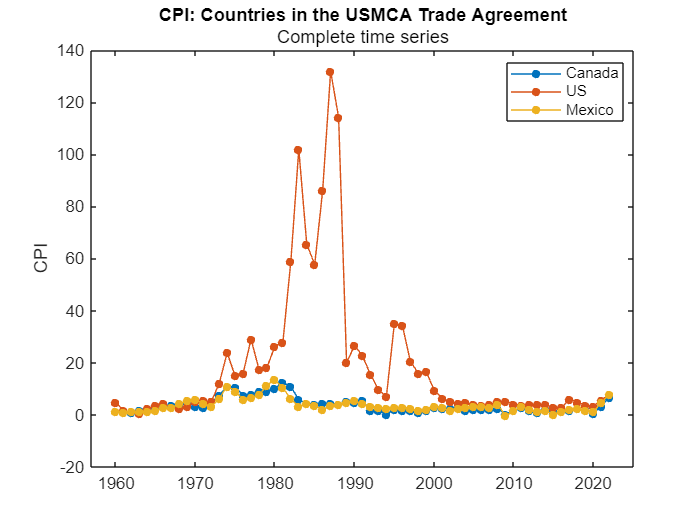

% Visual examination of the data 
fig = gscatter(cpiCountries.date, cpiCountries.cpi, cpiCountries.country);
set(fig, "linestyle", "-"); 
title("CPI: Countries in the USMCA Trade Agreement"); 
subtitle("Complete time series");
ylabel("CPI"); 
legend("Canada", "US", "Mexico")

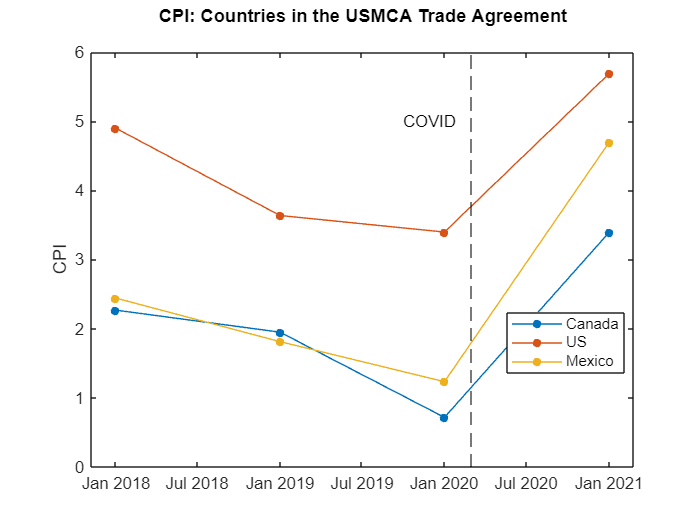

Error using exportgraphics
The value of 'handle' is invalid. Specified handle is not valid for export.


% Processing for time series 
cpiCountries = table2timetable(cpiCountries);
% Dates processing to get desired period of interest
cpiRecent = cpiCountries(timerange("2018-01-01", max(cpiCountries.date)), :);

% Visualize time series
fig = gscatter(cpiRecent.date, cpiRecent.cpi, cpiRecent.country);
set(fig, "linestyle", "-"); 
title("CPI: Countries in the USMCA Trade Agreement"); 
subtitle(" ");
ylabel("CPI"); 
xline(datetime(2020, 3, 1), "k--");
text(datetime(2020, 3, 1) - calmonths(5), 5, "COVID");
legend("Canada", "US", "Mexico");